# Reserve Variance Live Script 4

## Change Folder

cd("F:\OneDrive - Queensland University of Technology\Research Assistant " ...
    + "Work (OD)\Dispersal Variability (OD)\Code")

cd("C:\Users\sowen\OneDrive - Queensland University of Technology\" + ...
    "Research Assistant Work (OD)\Dispersal Variability (OD)\Code")

## Load Data

if ~exist("workspaceVarReserveVariance", 'var')
    if feature("numcores") == 12
        maxNumCompThreads(12);
    else
        maxNumCompThreads(16);
    end
    load matlabReserveVariance.mat
    setInterpLatex()
end

## Save Data

 if exist("workspaceVarReserveVariance", 'var')
     eval(clearVars());
     save matlabReserveVariance.mat
 end

% set the default intepreter to latex
setInterpLatex()

## Contents

Understanding Differences Between Regions

Closer Look at Biomass Contributions

Re-running the MPT Code for the Entire System

Full System Optimisation Results

## Assumptions / Notes

## Understanding Differences Between Regions

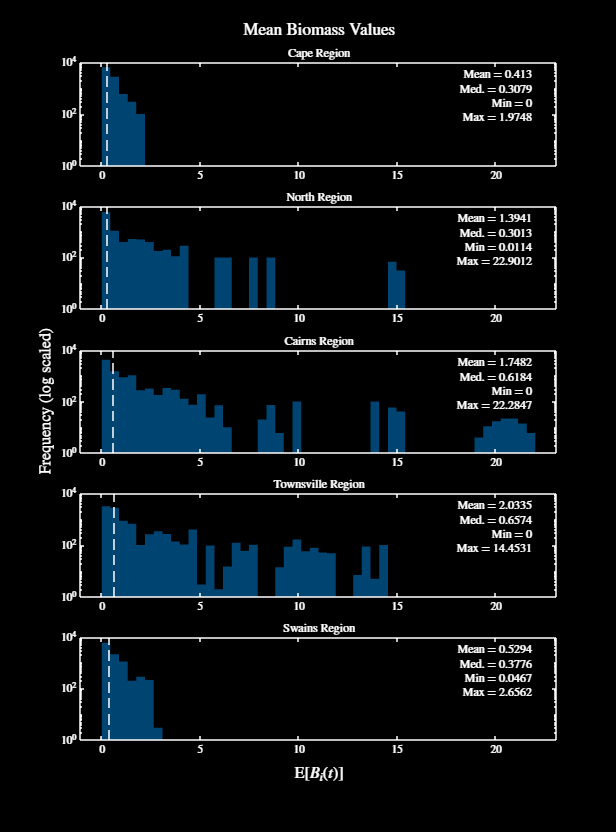

% let's look at the raw differences in biomass, and connectivity values
% methinks
axVec = plotConnectivityStats({simOutCellCape{1}.meanBiomassObs(:), ...
    simOutCellNorth{1}.meanBiomassObs(:), ...
    simOutCellCairns{1}.meanBiomassObs(:), ...
    simOutCellTowns{1}.meanBiomassObs(:), ...
    simOutCellSwains{1}.meanBiomassObs(:)}, "meanBiom", ...
    locNamesFull);
linkaxes(axVec, "y")
figResize(1.8)
% lightFig()
% saveFig("studyAreasBiomMeansDM")
darkFig()
saveFig("studyAreasBiomMeansDM")


% can't really see that much difference between these to be honest

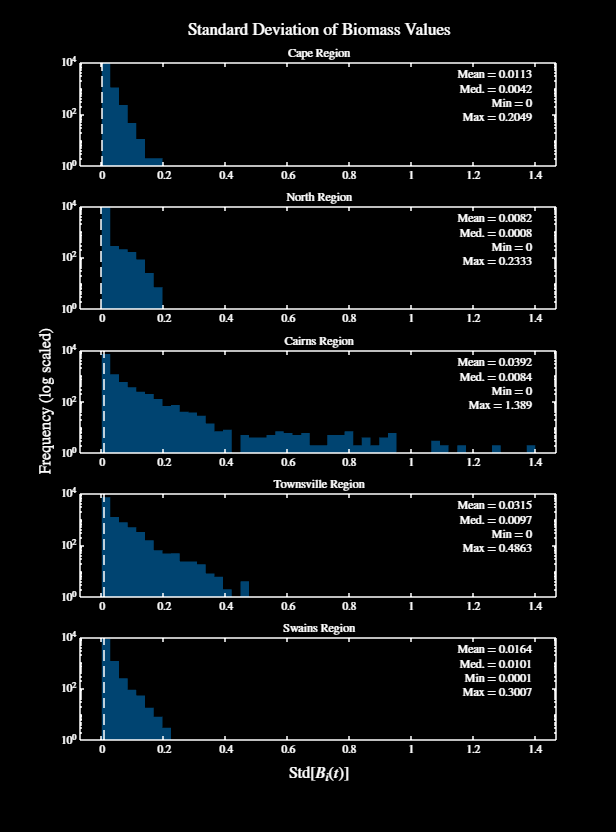

% fuck it - standard deviation times
axVec = plotConnectivityStats({simOutCellCape{1}.stdBiomassObs(:), ...
    simOutCellNorth{1}.stdBiomassObs(:), ...
    simOutCellCairns{1}.stdBiomassObs(:), ...
    simOutCellTowns{1}.stdBiomassObs(:), ...
    simOutCellSwains{1}.stdBiomassObs(:)}, "stdBiom", ...
    locNamesFull);
linkaxes(axVec, "y")
figResize(1.8)
% lightFig()
% saveFig("studyAreasBiomSDsDM")
darkFig()
saveFig("studyAreasBiomSDsDM")

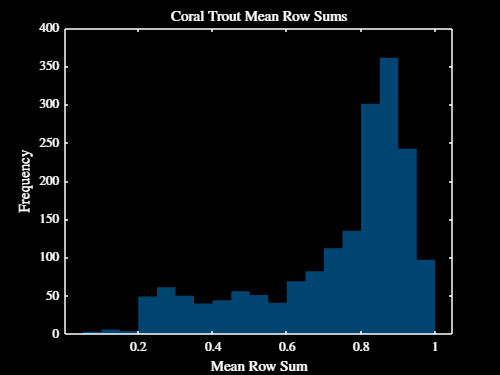

% wrote a note saying the mean values were high so let's have a geez
[meanConnCT, stdConnCT, ~, ~] ...
    = connectivityAnalysisReef(areaStructGBR.conMats, eps);
figure
histogram(meanConnCT, "EdgeAlpha", 0, "FaceColor", ...
            getColour('b'))
xlabel("Mean Row Sum")
ylabel("Frequency")
title("Coral Trout Mean Row Sums")
darkFig()
saveFig("coralTroutRowSums")

length(meanConnCT)

ans = 1804

length(areaStructGBR.conMats{1})

ans = 1903

## Shitty Sensitivity Analysis

% looking at how much randomising connectivity values will change the row
% sums, which is what we care about anyway
length(areaStructGBR.conMats)

ans = 30


% set the max variability above and below the original values we will
% investigate here
maxVar = 0.5;
var1 = [];
var2 = [];
for i = 1:length(areaStructGBR.conMats)

    % create a random matrix which will hold the percentage variability
    randMat = maxVar * (2 * rand(nReefsCT, nReefsCT) - 1) + 1;

    % perturb the matrix
    currMatRand = areaStructGBR.conMats{i} .* randMat;

    % store the row sums
    var1 = [var1; sum(areaStructGBR.conMats{i}, 2)];
    var2 = [var2; sum(currMatRand, 2)];

end
clear maxVar currMatRand randMat

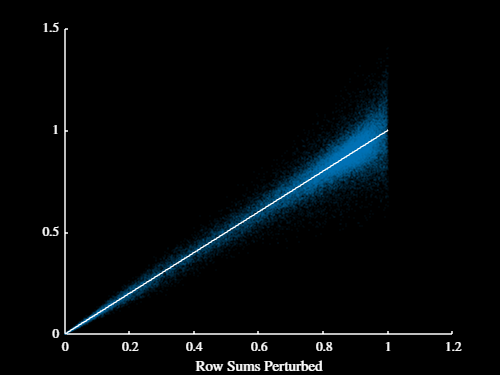

% plot the results
figure
hold on
scatter(var1, var2, 1, getColour('b'), 'filled', 'MarkerFaceAlpha', 0.1)
plot([0, 1], [0, 1], 'k', 'LineWidth', 0.1)
xlabel('Row Sums Original')
xlabel('Row Sums Perturbed')
darkFig()

% let's try a smarter version where we look at the wait nah screw it for
% now ceebs - wait nah don't screw it

% let's write out a good ol' set of variabilities to look into and some
% stuff to store results
maxVarVec = linspace(0, 0.5, 100);
rowSumsMeanCorr = zeros(length(maxVarVec), 1);
rowSumsVarCorr = zeros(length(maxVarVec), 1);

% loop over the maximum amounts of variability
for r = 1:length(maxVarVec)

    % store the current max variance
    maxVar = maxVarVec(r);

    % loop over the years
    rowSums = zeros(nReefsCT, nMatsCT);
    rowSumsRand = zeros(nReefsCT, nMatsCT);
    for i = 1:length(areaStructGBR.conMats)

        % create a random matrix which will hold the percentage variability
        randMat = maxVar * (2 * rand(nReefsCT, nReefsCT) - 1) + 1;

        % perturb the matrix, and calc row sums
        rowSumsRand(:, i) = sum(areaStructGBR.conMats{i} .* randMat, 2);
        rowSumsRand(rowSumsRand(:, i) > 1, i) = 1;
        rowSums = sum(areaStructGBR.conMats{i}, 2);

    end

    % calculate the mean and variance of the row sums
    rowSumsMean = mean(rowSums, 2);
    rowSumsRandMean = mean(rowSumsRand, 2);
    rowSumsVar = var(rowSums, [], 2);
    rowSumsRandVar = var(rowSumsRand, [], 2);

    % look at their rank correlation
    rowSumsMeanCorr(r) = corr(rowSumsMean, rowSumsRandMean, 'type', ...
        'Spearman');
    rowSumsVarCorr(r) = corr(rowSumsVar, rowSumsRandVar, 'type', 'Spearman');

end

% clear some shit
clear rowSumsRand currMatRand rowSums rowSumsMean rowSumsRandMean ...
    rowSumsVar rowSumsRandVar randMat

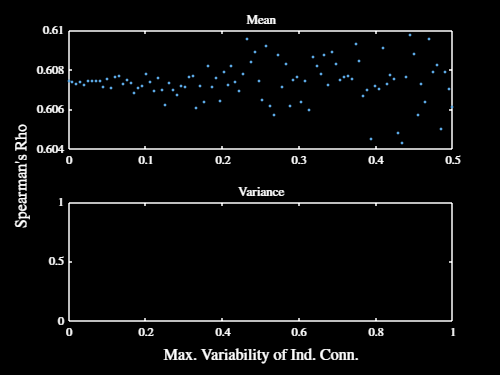

% plot some shit
figure
tL = tiledlayout(2, 1);
nexttile
plot(maxVarVec, rowSumsMeanCorr, '.')
title("Mean")
nexttile
plot(maxVarVec, rowSumsVarCorr, '.')
title("Variance")
xlabel(tL, 'Max. Variability of Ind. Conn.', 'interpreter', 'Latex')
ylabel(tL, 'Spearman''s Rho', 'interpreter', 'Latex')
darkFig()


% the above doesn't really make a lot of sense - should probably look into
% those results methinks - but anyway fuck it give this stuff a rest for
% now anyway methinks

## Closer Look at Biomass Contributions

% want to understand better the biomass contributions for each of the age
% classes, and how they spread across if we assume a uniform input of
% larvae
specStructCT.successVec

ans =     0.6000    0.7000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900


specStructCT.massVec

ans =     0.1229    0.2092    0.2698    0.3123    0.3421    0.3631    0.3778    0.3881    0.3953    0.4004    0.4040    0.4065    0.4082    0.4095


actionStructCT.actionEffect

ans =     0.6000    0.7000    0.8300    0.9400    0.9400    0.9400    0.9400    0.9400    0.9400    0.9400    0.9400    0.9400    0.9400


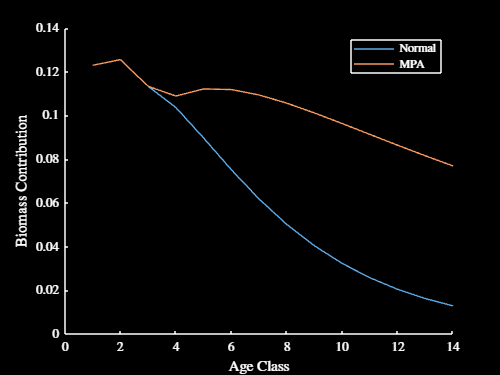


% alright, cumprod time
var1 = [1, cumprod(specStructCT.successVec)];
var2 = [1, cumprod(actionStructCT.actionEffect)];

% let's now look at the biomass contributions from each
var3 = var1 .* specStructCT.massVec;
var4 = var2 .* specStructCT.massVec;

figure
hold on
plot(var3)
plot(var4)
ylabel("Biomass Contribution")
xlabel("Age Class")
legend("Normal", "MPA")
darkFig()

## Re-running the MPT Code for the Entire System

% fuck my life barry but fair enough to be honest

% alright - the function that is the parent function for all of this is:
runMPASimulation()

% the function that does the optimisation is the chooseMPA function:
chooseMPA()

% the function I'm now writing that will do the better version of mpt is:
applyMptSystem()

% before I do any of this, going to save the old .mat data here xd
% save matlabReserveVarianceBeforeSystemWideMPT.mat

% note - given I'm now going to be saving the data, I should probably see
% if I can in fact try to use the saved data from the original runs to
% speed things up - would probably be very much useful

% could then prioritise running the edge cases first for all of the cases -
% this would be the most efficient approach actually

% will need to write out a bunch of shit here, gonna need to run these over
% each of the 5 study areas

% alright, gonna do the Cape region first

% ensure parallel processes are cancelled
if exist('futureVecFinCape', 'var')
    cancelFutureVec(futureVecFinCape);
    clear futureVecFinCape
end

% run in parallel
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    methodStruct.actionEffect = 2.5;
    futureVecFinCape(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructCape, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct, "saveCape");
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 14 workers.


% save the data
if checkFutureVec(futureVecFinCape)
    for i = 1:length(futureVecFinCape)
        simOutCellCape{14 + i} = fetchOutputs(futureVecFinCape(i));
    end
    % clear futureVecFinCape
end

Futures have completed succesfully.


% alright, gonna do the North region next

% ensure parallel processes are cancelled
if exist('futureVecFinNorth', 'var')
    cancelFutureVec(futureVecFinNorth);
    clear futureVecFinNorth
end

% run in parallel
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    methodStruct.actionEffect = 2.5;
    futureVecFinNorth(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructNorth, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct, "saveNorth");
end

% save the data
if checkFutureVec(futureVecFinNorth)
    for i = 1:length(futureVecFinNorth)
        simOutCellNorth{14 + i} = fetchOutputs(futureVecFinNorth(i));
    end
    % clear futureVecFinNorth
end

Futures have completed succesfully.


% alright, gonna do the Cairns region next

% ensure parallel processes are cancelled
if exist('futureVecFinCairns', 'var')
    cancelFutureVec(futureVecFinCairns);
    clear futureVecFinCairns
end

% run in parallel
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    methodStruct.actionEffect = 2.5;
    futureVecFinCairns(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructCairns, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct, "saveCairns");
end

% save the data
if checkFutureVec(futureVecFinCairns)
    for i = 1:length(futureVecFinCairns)
        simOutCellCairns{14 + i} = fetchOutputs(futureVecFinCairns(i));
    end
    % clear futureVecFinCairns
end

Futures have completed succesfully.


% alright, gonna do the Towns region next

% ensure parallel processes are cancelled
if exist('futureVecFinTowns', 'var')
    cancelFutureVec(futureVecFinTowns);
    clear futureVecFinTowns
end

% run in parallel
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    methodStruct.actionEffect = 2.5;
    futureVecFinTowns(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructTowns, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct, "saveTowns");
end

% save the data
if checkFutureVec(futureVecFinTowns)
    for i = 1:length(futureVecFinTowns)
        simOutCellTowns{14 + i} = fetchOutputs(futureVecFinTowns(i));
    end
    % clear futureVecFinTowns
end

Futures have completed succesfully.


% alright, gonna do the Swains region next

% ensure parallel processes are cancelled
if exist('futureVecFinSwains', 'var')
    cancelFutureVec(futureVecFinSwains);
    clear futureVecFinSwains
end

% run in parallel
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
for i = 1:length(methodStringVec)
    methodStruct.methodInd = methodStringVec(i);
    methodStruct.meanVarWeight = weightVec(i);
    methodStruct.actionEffect = 2.5;
    futureVecFinSwains(i) = parfeval(@runMPASimulation, 1, simStructFin, ... 
        areaStructSwains, areaStructGBR, specStructCT, randStructFin, ... 
        actionStructFin, methodStruct, "saveSwains");
end

% save the data
if checkFutureVec(futureVecFinSwains)
    for i = 1:length(futureVecFinSwains)
        simOutCellSwains{14 + i} = fetchOutputs(futureVecFinSwains(i));
    end
    % clear futureVecFinSwains
end

Futures have completed succesfully.


## Extra Figure for Analytical Section

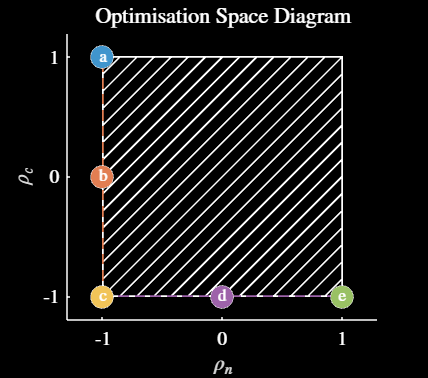

% need to form a new figure here for the analytical section methinks
figure
hold on
var3 = 1.25;

% figure out how to make diagonal lines
var1 = linspace(1, -1, 15);
var2 = flip(var1);
for i = 1:length(var1)
    plot([-1, var1(i)], [var2(i), 1], 'k', 'LineWidth', var3)
    plot([var2(i), 1], [-1, var1(i)], 'k', 'LineWidth', var3)
end

% plot the boundary of the feasible region
pointsX = [-1, -1, 1, 1, -1];
pointsY = [1, -1, -1, 1, 1];
plot(pointsX, pointsY, '-k', 'LineWidth', var3)

% plot the edges for b and d
plot([-1, -1], [-1, 1], '--', 'Color', getColour(2), 'LineWidth', var3)
plot([-1, 1], [-1, -1], '--', 'Color', getColour(4), 'LineWidth', var3)

% make a vector of the points I want to plot, along with their text
pointsX = [-1, -1, -1, 0, 1];
pointsY = [1, 0, -1, -1, -1];
textVec = ["a", "b", "c", "d", "e"];

% plot the points as coloured circles hehe
hold on
nodeSize = 90;
labelSize = 15;
nodeSize = 50;
labelSize = 10;
for r = 1:length(textVec)
    plot(pointsX(r), pointsY(r), 'k.', 'MarkerSize', 1.05 * nodeSize)
    plot(pointsX(r), pointsY(r), '.', 'MarkerSize', nodeSize, 'Color', ...
        getColour(r))
    text(pointsX(r), pointsY(r), textVec(r), "FontSize", labelSize, ...
        'Color', 'w', 'FontWeight', 'bold', 'lineStyle', 'none', ...
        'EdgeColor', 'none', 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'middle')
end
xticks([-1, 0, 1])
yticks([-1, 0, 1])
figResize(1, 0.85)
axis([-1.2, 1.2, -1.2, 1.2])
axis equal
box off
xlabel("$\rho_n$")
ylabel("$\rho_c$")
title("Optimisation Space Diagram")
setFontSize(16)
lightFig()
saveFig("optimSpaceDiagram")
darkFig()
saveFig("optimSpaceDiagramDM")


clear pointsX pointsY textVec

## Full System Optimisation Results

% need to load in the results from some of the other trials - for now,
% pretty sure it's just the cape that is done
var1 = dir('../Data/mpaSimOutputs/');
var1.name

ans = '.'

ans = '..'

ans = 'MPTBiomSys_0.25_Cape.mat'

ans = 'MPTBiomSys_0.5_Cape.mat'

ans = 'MPTBiomSys_0.75_Cape.mat'

ans = 'MPTBiomSys_0_Cape.mat'

ans = 'MPTBiomSys_0_North.mat'

ans = 'MPTBiomSys_1_Cape.mat'

ans = 'MPTBiomSys_1_North.mat'

ans = 'MPTLarvContSys_0.25_Cape.mat'

ans = 'MPTLarvContSys_0.5_Cape.mat'

ans = 'MPTLarvContSys_0.75_Cape.mat'

ans = 'MPTLarvContSys_0_Cape.mat'

ans = 'MPTLarvContSys_0_North.mat'

ans = 'MPTLarvContSys_1_Cape.mat'

ans = 'MPTLarvContSys_1_North.mat'

% check the contents of the file so that I don't forgeor
whos -file ../Data/mpaSimOutputs/MPTBiomSys_0.5_Cape.mat

  Name              Size             Bytes  Class     Attributes

  simOutStruct      1x1             140358  struct              



% will first need to save the results from the trials, starting with the
% cape
methodStringVec = ["MPTBiomSys", "MPTBiomSys", "MPTBiomSys", "MPTBiomSys", ...
    "MPTBiomSys", "MPTLarvContSys", "MPTLarvContSys", "MPTLarvContSys", ...
    "MPTLarvContSys", "MPTLarvContSys"];
weightVec = [1, 0.75, 0.5, 0.25, 0, 1, 0.75, 0.5, 0.25, 0];
regionNames = ["Cape", "North", "Cairns", "Towns", "Swains"];
for i = 1:length(methodStringVec)
    for r = 1:length(regionNames)
        if isfile("../Data/mpaSimOutputs/" + methodStringVec(i) + "_" ...
            + num2str(weightVec(i)) + "_" + regionNames(r) + ".mat")
            load("../Data/mpaSimOutputs/" + methodStringVec(i) + "_" ...
                + num2str(weightVec(i)) + "_" + regionNames(r) + ".mat")
        elseif isfile("../Data/mpaSimOutputs/" + methodStringVec(i) + "_" ...
            + strrep(num2str(weightVec(i)), ".", "p") ...
            + "_" + regionNames(r) + ".mat")
            load("../Data/mpaSimOutputs/" + methodStringVec(i) + "_" ...
            + strrep(num2str(weightVec(i)), ".", "p") ...
            + "_" + regionNames(r) + ".mat")
        end
        eval("simOutCell" + regionNames(r) + "{14 + i} = simOutStruct;")
    end
end

% ok because matlab somehow cooked it with using the older version of the
% function (beats me man), I need to re-run a bunch of these to fix them
% methinks

randStruct.randType = "sequence";
for i = 15:length(simOutCellNorth)
    simOutCellNorth{i} = rerunMPASimulation2(simStructFin, ...
        areaStructNorth, areaStructGBR, specStructCT, randStruct, ...
        actionStructFin, simOutCellNorth{i});
end

randStruct.randType = "sequence";
for i = 15:length(simOutCellTowns)
    simOutCellTowns{i} = rerunMPASimulation2(simStructFin, ...
        areaStructTowns, areaStructGBR, specStructCT, randStruct, ...
        actionStructFin, simOutCellTowns{i});
end

randStruct.randType = "sequence";
for i = 15:length(simOutCellSwains)
    simOutCellSwains{i} = rerunMPASimulation2(simStructFin, ...
        areaStructSwains, areaStructGBR, specStructCT, randStruct, ...
        actionStructFin, simOutCellSwains{i});
end

% note - also need to make sure that the actionStructFin, in terms of like
% the survival probabilities, is the same across all of my 14 runs etc -
% could standardise this by doing the rerunMPASimulation2() just for
% everything, but this is probably just a bit of overkill

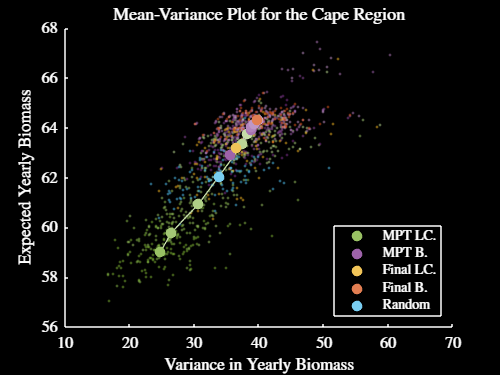

% let's plot the results from the cape
figure
plotFinalResults(simOutCellCape, "Cape", [], "sys")
setFontSize(13)
lightFig()
saveFig("meanVarSpaceCapeSys")
darkFig()
saveFig("meanVarSpaceCapeSysDM")

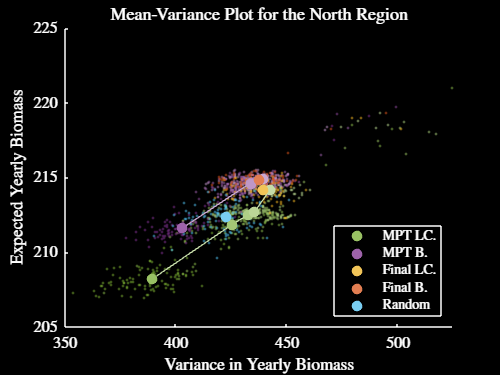

% let's plot the results from the north
figure
plotFinalResults(simOutCellNorth, "North", [], "sys")
setFontSize(13)
xlim([350, 525])
ylim([205, 225])
lightFig()
saveFig("meanVarSpaceNorthSys")
darkFig()
saveFig("meanVarSpaceNorthSysDM")

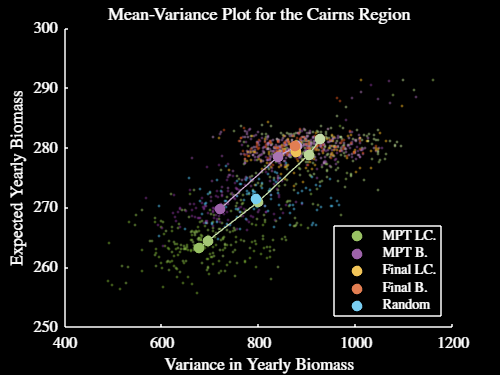

% let's plot the results from the cairns
figure
plotFinalResults(simOutCellCairns, "Cairns", [], "sys")
setFontSize(13)
xlim([400, 1200])
ylim([250, 300])
lightFig()
saveFig("meanVarSpaceCairnsSys")
darkFig()
saveFig("meanVarSpaceCairnsSysDM")

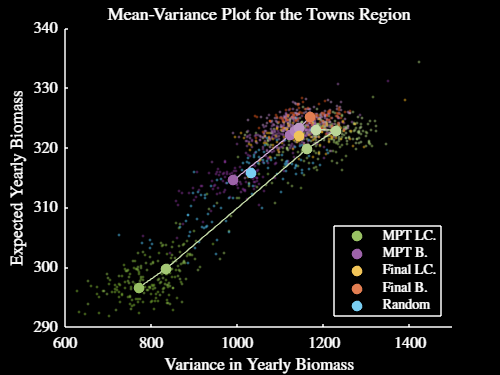

% let's plot the results from the towns
figure
plotFinalResults(simOutCellTowns, "Towns", [], "sys")
setFontSize(13)
xlim([600, 1500])
ylim([290, 340])
lightFig()
saveFig("meanVarSpaceTownsSys")
darkFig()
saveFig("meanVarSpaceTownsSysDM")

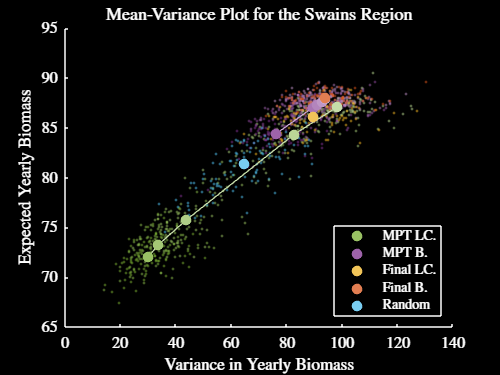

% let's plot the results from the swains
figure
plotFinalResults(simOutCellSwains, "Swains", [], "sys")
setFontSize(13)
% ylim([50, 70])
% figResize(1.2)
lightFig()
saveFig("meanVarSpaceSwainsSys")
darkFig()
saveFig("meanVarSpaceSwainsSysDM")

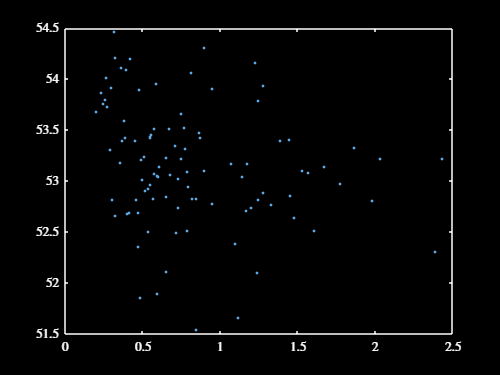

% just to check my sanity, let's load in a couple of the files and just
% check how they're going
load("../Data/mpaSimOutputs/MPTLarvContSys_0p5_Swains.mat")
figure
plot(simOutStruct.objFuncVar, simOutStruct.objFuncExpVal, '.')
darkFig()

ans = 32

ctr1 = 0

ctr2 = 1

ans = struct with fields:
             mpaSel: {100×1 cell}
         objFuncTot: [100×1 double]
          objFuncTS: {100×1 cell}
      objFuncExpVal: [100×1 double]
         objFuncVar: [100×1 double]
    objFuncTotRetro: [100×1 double]
     objFuncTSRetro: {100×1 cell}
           exitFlag: [100×1 double]
       methodStruct: [1×1 struct]


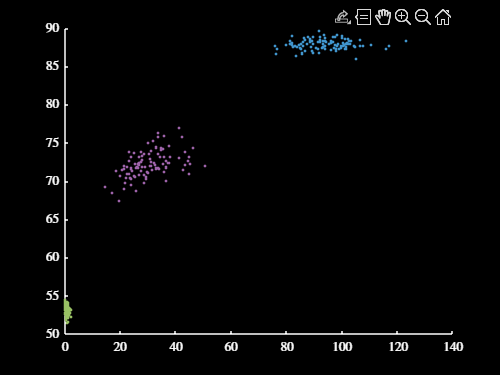

specStructCT = struct with fields:
         alpha: 1.5000e-05
          beta: 1.0000e-08
    successVec: [0.6000 0.7000 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900]
     fecundVec: [5.6556e+04 2.8326e+05 6.1196e+05 9.5337e+05 1.2570e+06 1.5049e+06 1.6972e+06 1.8415e+06 1.9476e+06 2.0244e+06 2.0796e+06 2.1189e+06 2.1468e+06 2.1665e+06]
    weightings: [0.1229 0.2092 0.2698 0.3123 0.3421 0.3631 0.3778 0.3881 0.3953 0.4004 0.4040 0.4065 0.4082 0.4095]
       massVec: [0.1229 0.2092 0.2698 0.3123 0.3421 0.3631 0.3778 0.3881 0.3953 0.4004 0.4040 0.4065 0.4082 0.4095]


ans =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


ans =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


ans = "MPTBiomSys"

sum(simOutStruct.mpaSel{1})